# Laboratorio 2 

## Robótica 2021 - 1 

### Luis Alberto Chavez Castro

### Jorge Luis Reina

### Edwin Alexander Casallas

##  Modelo cinemático inverso *fanuc LR Mate 200 ib*

### **Parte I, Robot y Ruta.**

El robot asignado para el desarrolllo de este laboratorio fue el modelo* fanuc LR Mate 200 ib, Se asigna un modelo de robot industrial a cada equipo de trabajo y un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentar al menos la simulación de esa ruta, pueden crear y simular otras rutas y/o otros planos..*

### Localización de ruta.

Plano - Vector, significa que la ruta que el robot va a simular debe estar en un plano normal al vector indicado en la tabla.

La ruta debe tener una de las dos formas mostradas en la figura 2. Cada grupo selecciona la que deseen.

La dimensión L debe ser aproximadamente 0,4 del alcance horizontal máximo del robot.

El grupo decide la posición de la ruta en el espacio cartesiano de manera que quede dentro del espacio diestro del robot.

la ruta seleccionada por el equipo de trabajo es la que se muestra a continuación:

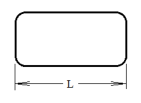

### Características y modelo del robot

Busque información t´ ecnica del robot, obtenga catálogos de fabricante, presente en el informe:

#### 1. Imagen del robot.

el Robot a modelar es el siguiente:

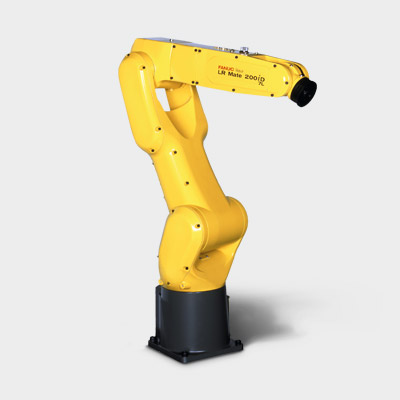

#### 2. Capacidad de carga.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iD posee una capacidad de carga de 7Kg

#### 3. Alcance vertical y horizontal.

El  Robot multiusos de productividad elevada FANUC LR Mate 200iD hace parte de la gaa de mini robots que buscan emular las longitudes de un brazo humano, por lo que su alcance máximo es de 717mm

en su punto máximo suerior logra 997mm en altura, medidos desde la base de instalacion del robot, hacia el frente logra su extension de 717mm y hacia la parte trasera del mismo logra un alcance de 617mm desde su origen.

#### 4. Repetibilidad.

La repetiiblidad de este robot esta el rango de las centecimas de milimetro, segun el fabricante es de +/-0.01 mm.

#### 5. Gráfica(s) de espacio alcanzable.

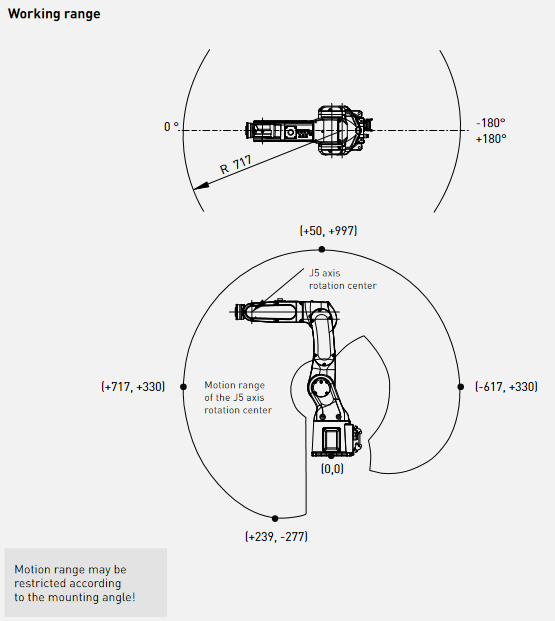

#### 6. Tabla de parámetros DH.

# FALTA

#### 7. Qué software utiliza el fabricante para diseño de celdas o programación.

el Fabricante Fanuc, emplea su propio software llamado  ROBOTSE SOFTWARE y para este robot el controlador  estándar de Fanuc  R-30iB Plus  es el que mejor se adapta a las necesidades de control de este modelo en especifico.

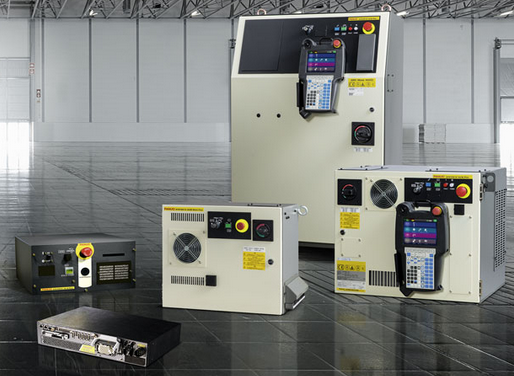

por otra parte se el mando a distancia en esta familia de robots se conoce como i-pendant y se muestra a continuacion

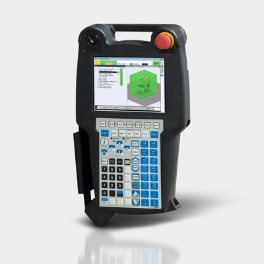


%% Robot RPRRR 5 gdl
clf
clc
L1 = 2;L2 = 1; L3 = 1;L4 = 0.707*1;L5 =0.707*1; 
L4a = 0.707*1;
% ws =   [-10 10 -10   10 -10 10];
ws = [-70 80 -70 80 -20 70]/10;

 plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };

%            Theta  d   a   alpha  type mdh offset  qlim
% L(1) = Link('revolute'   ,'alpha',      0,  'a',  0,     'd',    L1 , 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3],   'modified');
% L(2) = Link('prismatic'  ,'alpha',  -pi/2,  'a',  0, 'theta',     0 , 'offset',    L2, 'qlim',       [0     7*1],   'modified');
% L(3) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     L3, 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3],   'modified');
L(1) = Link('revolute'   ,'alpha',      0,  'a',  0,     'd',    L1 , 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3],   'modified');
L(2) = Link('prismatic'  ,'alpha',  -pi/2,  'a',  0, 'theta',     0 , 'offset',    L2, 'qlim',       [0     7*1],   'modified');
L(3) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     L3, 'offset', -pi/2, 'qlim',  [-2*pi/3 2*pi/3],      'modified');
L(3) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     L3, 'offset', -pi/2, 'qlim',  [-2*pi/3 2*pi/3],      'modified');
L(4) = Link('revolute'   ,'alpha',  -pi/2,  'a',  0,     'd',     0 , 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');
L(5) = Link('revolute'   ,'alpha',  -pi/2,  'a',  L4a,   'd',     L4, 'offset',     0, 'qlim',  [-2*pi/3 2*pi/3], 'modified');

Robot = SerialLink(L,'name','Robot_RPRRR','plotopt',plot_options)


%%
Robot.tool = [ 0  0   1  L5;...
               1  0   0  0 ;...
               0  1   0  0 ;...
               0  0   0  1  ];

%%
q = [0 0 0 0 0];

Robot.teach(q)

%%
hold on
trplot(eye(4),'length',2 )

%% Solucion problena geometrico directo
TCP = Robot.fkine(q)
trplot(TCP,'length',2 )
tr2rpy(TCP,'zyx','deg')


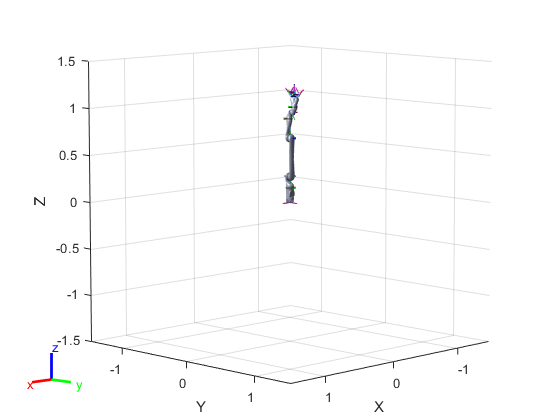

Unrecognized property 'tool' for class 'rigidBodyTree'.